clear
%hold off;
syms x y z alpha beta delta

[t, Y] = ode45(@vdp5, [0, 20], [20 20 0])

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Y =    20.0000   20.0000         0
   20.0000   20.0001    0.0001
   20.0000   20.0001    0.0001
   20.0000   20.0002    0.0002
   20.0000   20.0002    0.0002
   20.0000   20.0005    0.0005
   20.0000   20.0007    0.0007
   20.0000   20.0010    0.0010
   20.0000   20.0012    0.0012
   20.0000   20.0025    0.0025
   20.0000   20.0037    0.0037
   20.0000   20.0050    0.0050
   20.0000   20.0062    0.0062
   20.0000   20.0125    0.0125
   20.0000   20.0188    0.0188


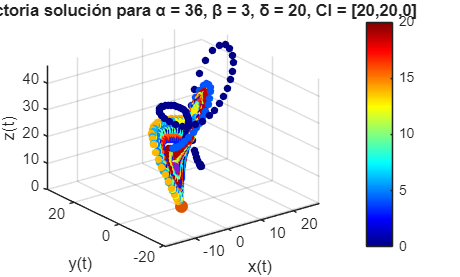

figure;


% Trayectoria
scatter3(Y(:,1), Y(:,2), Y(:,3), 20, t, 'filled');   % 20 = tamaño de punto
colormap jet
colorbar
hold on

scatter3(0, 0, 0, 60, 'filled')
hold on
scatter3(sqrt(60), sqrt(60), 20, 60, 'filled')
hold on
scatter3(-sqrt(60), -sqrt(60), 20, 60, 'filled')
hold on

grid on
%xlim([-12 30])
%ylim([-20 30])
%zlim([0 55])
xlabel('x(t)'); ylabel('y(t)'); zlabel('z(t)');
title('Trayectoria solución para α = 36, β = 3, δ = 20, CI = [20,20,0]')